% Pulse Position Modulation
clc;
clear;
fs=1000; % Samplping frequency
t=0.5;
n=0:1/fs:t;
n=n(1:end-1);

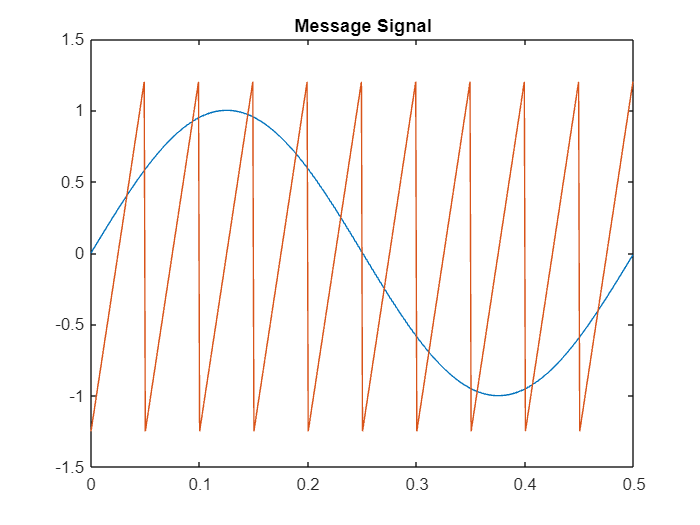

% Message Signal
fm=2; % Freq of message signal
fc=20; % Freq of carrier signal
duty=10;
sqr_period=fs/fc; % No of samples in one square period
on_time=sqr_period/duty; % No of samples in on time
A=1.25;
st=A*sawtooth(2*pi*fc*n); % Sawtooth generation
mn=sin(2*pi*fm*n);
plot(n,mn);
hold on 
plot(n,st);
hold off
title("Message Signal");

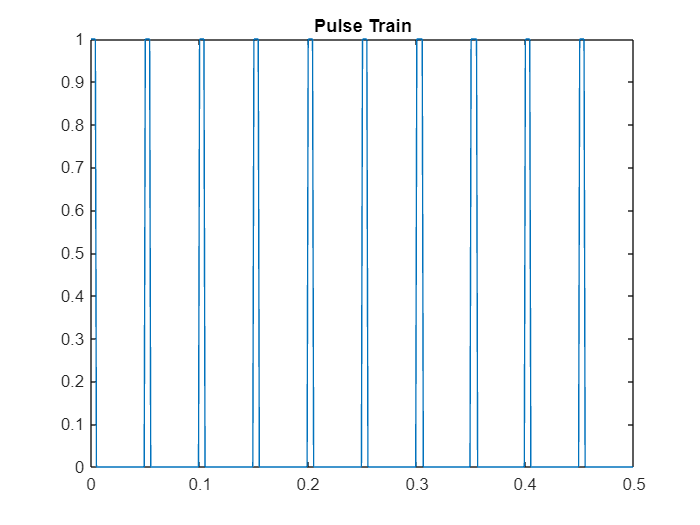

s=square(2*pi*fc*n,duty);
s(find(s<0))=0;
plot(n,s);
title("Pulse Train");

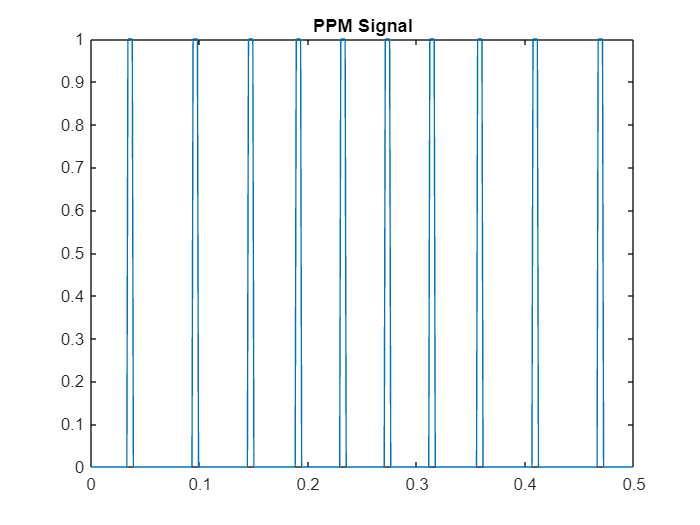

ppm=zeros(1,length(s));
id=find(st>mn);
idd=diff(id);
iddd=find(idd~=1);
temp(1)=id(1);
temp(2:length(iddd)+1)=id(iddd+1);

% PPM Signal\
for i=1:length(temp)
    ppm(temp(i):temp(i)+on_time-1)=1;
end
plot(n,ppm);
title("PPM Signal");